clear all; close all; clc;
warning('off','all');

clear all;
%% Global variables
global width amplitude
global x_result

%% Initialization of the optimization routine
x_result = [];
x_guess  = [0.05; 0.125];  

%% Optimization routine
options = optimset('PlotFcns',@optimplotfval);
disp('Optimization started...')

Optimization started...


disp(' ')

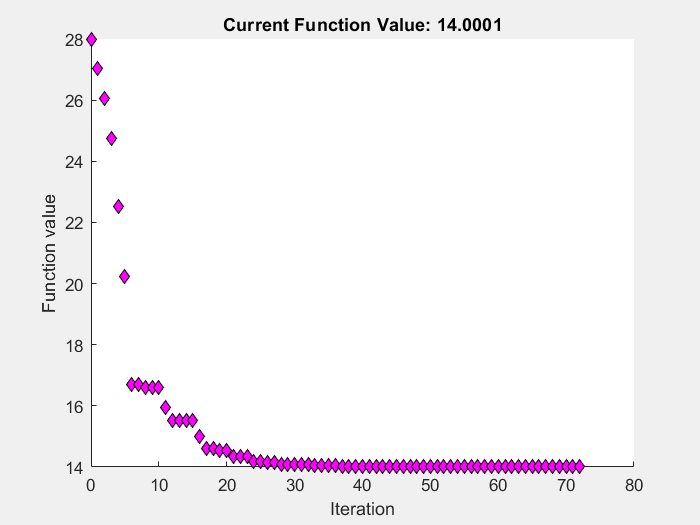

x_opt =     0.1000
    0.2500


V_result = 14.0001

[x_opt, V_result] = fminsearch('Opti_Clamp', x_guess, options)

disp(' ')

disp('...optimization finished!')

...optimization finished!


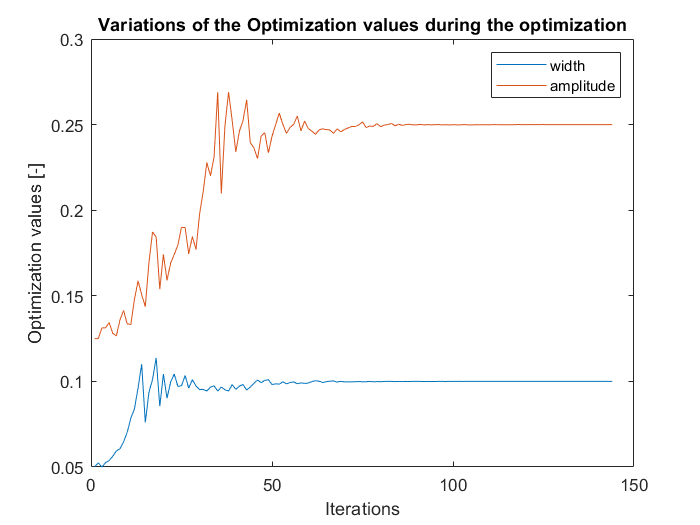


%% Plots
figure;
plot(x_result); legend('width ','amplitude');
xlabel('Iterations')
ylabel('Optimization values [-]')
title('Variations of the Optimization values during the optimization')

More information on *fminsearch *can be found [here](https://nl.mathworks.com/help/matlab/ref/fminsearch.html). 

More information on the algorithm of *fminsearch* can be found [here](https://nl.mathworks.com/help/optim/ug/fminsearch-algorithm.html).